# Young's experiment

% Jonghwan Lee, Mar 2021

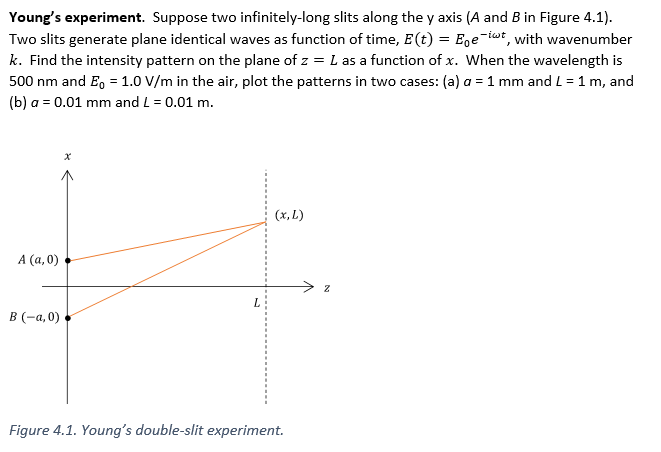

Given parameters.  All lengths are in [m].

clear
c = 3e8;
eps0 = 8.85e-12;
n = 1;
E0 = 1;
lam = 500e-9;
a = 1e-3;
L = 1;

k and omega

k = 2*pi/lam;
w = k*c;

Sample x.

dx = 10e-6;
x = -10e-3:dx:10e-3;

E1 and E2

l1 = sqrt( (x-a).^2 + L^2 );
l2 = sqrt( (x+a).^2 + L^2 );
E1 = E0 * exp(1i*k*l1);
E2 = E0 * exp(1i*k*l2);

Intensity

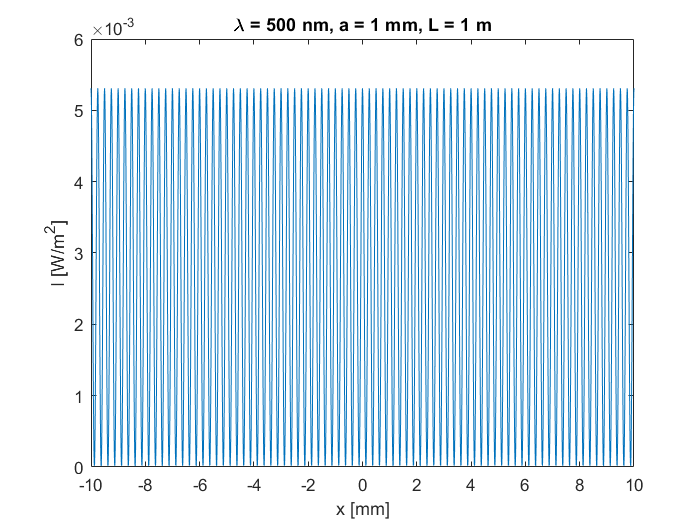

I = 1/2 * n * c * eps0 * abs(E1+E2).^2;

figure
plot(x*1e3,I)
xlabel('x [mm]')
ylabel('I [W/m^2]')
title(['\lambda = ' num2str(lam*1e9) ' nm, a = ' num2str(a*1e3) ' mm, L = ' num2str(L) ' m'])

Second case

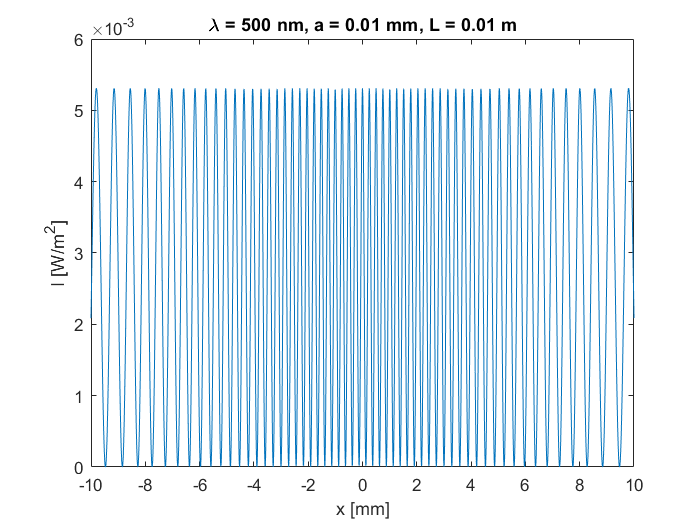

a = 1e-5;
L = 0.01;

l1 = sqrt( (x-a).^2 + L^2 );
l2 = sqrt( (x+a).^2 + L^2 );
E1 = E0 * exp(1i*k*l1);
E2 = E0 * exp(1i*k*l2);

I = 1/2 * n * c * eps0 * abs(E1+E2).^2;

figure
plot(x*1e3,I)
xlabel('x [mm]')
ylabel('I [W/m^2]')
title(['\lambda = ' num2str(lam*1e9) ' nm, a = ' num2str(a*1e3) ' mm, L = ' num2str(L) ' m'])

Symbolic

clear all
syms k omega E0 a L x t positive

L1 = sqrt((x-a)^2+L^2)  % optical pathlength of the wave from A

$$L1 = \sqrt{L^{2}+{\left(a-x\right)}^{2}}$$

E1 = E0 * exp(-1i*omega*t) * exp(1i*k*L1)

$$E1 = E_{0}\,{\mathrm{e}}^{k\,\sqrt{L^{2}+{\left(a-x\right)}^{2}}\,\mathrm{i}}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}$$


L2 = sqrt((x+a)^2+L^2)

$$L2 = \sqrt{{\left(a+x\right)}^{2}+L^{2}}$$

E2 = E0 * exp(-1i*omega*t) * exp(1i*k*L2)

$$E2 = E_{0}\,{\mathrm{e}}^{k\,\sqrt{{\left(a+x\right)}^{2}+L^{2}}\,\mathrm{i}}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}$$


E = E1 + E2;
I = E * conj(E)

$$I = \begin{array}{l} \left(E_{0}\,{\mathrm{e}}^{-\sigma_{2}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}+E_{0}\,{\mathrm{e}}^{-\sigma_{1}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\right)\,\left(E_{0}\,{\mathrm{e}}^{\sigma_{2}}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+E_{0}\,{\mathrm{e}}^{\sigma_{1}}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}\right)\\ \mathrm{where}\\ \sigma_{1}=k\,\sqrt{L^{2}+{\left(a-x\right)}^{2}}\,\mathrm{i}\\ \sigma_{2}=k\,\sqrt{{\left(a+x\right)}^{2}+L^{2}}\,\mathrm{i} \end{array}$$

simplify(I)

$$ans = \begin{array}{l} \left(E_{0}\,{\mathrm{e}}^{-\sigma_{2}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}+E_{0}\,{\mathrm{e}}^{-\sigma_{1}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\right)\,\left(E_{0}\,{\mathrm{e}}^{\sigma_{2}}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+E_{0}\,{\mathrm{e}}^{\sigma_{1}}\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}\right)\\ \mathrm{where}\\ \sigma_{1}=k\,\sqrt{L^{2}+{\left(a-x\right)}^{2}}\,\mathrm{i}\\ \sigma_{2}=k\,\sqrt{{\left(a+x\right)}^{2}+L^{2}}\,\mathrm{i} \end{array}$$